**Essentials of Ultrasound Imaging: Lecture 2**

**GUI: Continuous Wave Reverberation Version 2**

**Author: Joseph Greene**

**Reference: Chapter 3.3, Diagnostic Ultrasound Imaging: Inside Out Ed.2**

Brief Description: In this Live Editor, we will explore how the Pulsed Wave Reverb GUI Calulates reflected and transmitted power for a three layered media. Next, we will see how the GUI manipulates that data to derive a basic plot showing those results.

Inputs: z1 (impedence of layer 1), z2, z3, c2, (speed of sound in layer 2), d2 (thickness of layer 2)

Outputs: Graph (Transmission amplitude over time), Transmission_Values (Array of the amplitudes transmitted) 

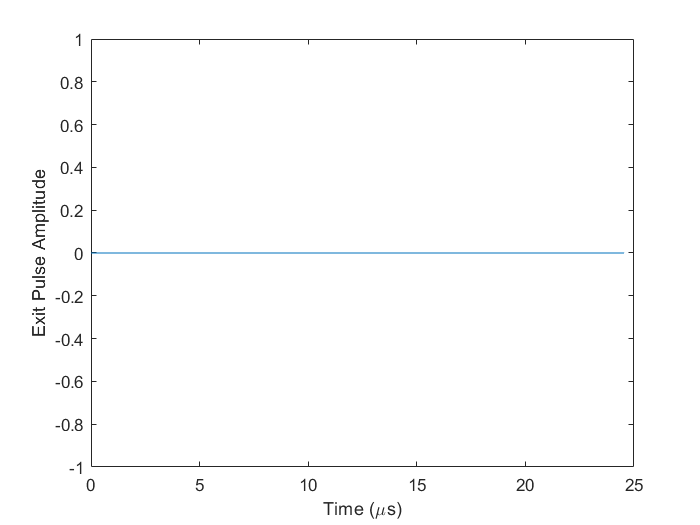

clc
clear
close all


%%%%%%%%%%%%
%User Inputs
%%%%%%%%%%%%
%Impedences of Layers 1 - 3
z1 = 1*10^6; %MRayls
z2 = 3*10^6;
z3 = 9*10^6;

%Material properties of second layer, speed of sound and thickness
c2 = 1.54; %Km/s
d2 = 3; %mm

%%%%%%%%%%%%%
%Calculations
%%%%%%%%%%%%%

% Set the color matrix's coordinates, xS, yS and zS
list12 = [-.2 0 .2 .4 .6 .8 1]'; % x coordinates, y coordinates is fixed on .55
list23 = [-.1 .1 .3 .5 .7 .9]'; % x coordiantes for face 2-3 , y coordinates i fixed on -.55

%How many time points per path in layer 2
nBase = 10;
nSamplePerPath = 30;
nPath = 12;
nSampleInitial = round(nSamplePerPath*0.5/1.1);
nSampleTot = nPath*nSamplePerPath + nSampleInitial;

% Wave from layer 1 to 2 -> Note, only longitudinal waves used! 
tf12 = 2*z2/(z1+z2); %Transmission 
% Wave from layer 2 to 1
rf21 = (z1-z2)/(z1+z2); %reflection

% Wave from layer 2 to 3 -> Longitudinal, no shear wave
% calculations
rf23 = (z3-z2)/(z3+z2); %Second boundary reflection
tf23 = 2*z3/(z3+z2); %Second boundary transmission

waves = zeros(nSampleTot+1,nSampleTot); %Preallocate time points for plotted wave

vecPath = ones(1,nSamplePerPath); %One path wave travels
diagVec = ones(1,nSampleInitial); %Path wave travels along diagonals
for k = 0:5
%             diagVec = [diagVec, ...
%                 tf12 * rf21.^k * rf23.^k *vecPath, ...
%                 tf12 * rf21.^k * rf23.^(k+1) *vecPath];
    diagVec = [diagVec, vecPath, vecPath];
end
%Preallocate
timeVec = zeros(1,nSampleInitial);
timePath = zeros(1,2*nSamplePerPath-1);
for k = 0:5 %Reflectance/Transmittance @ each interface
    timeVec = [timeVec, timePath, tf12 * tf23 * rf21.^k * rf23.^k];
end

waves(2:end,:) = diag(diagVec);

xS = zeros(2,nSampleTot,7);
yS = xS;

xdata = linspace(-.2,-.2,nSampleInitial);
ydata = linspace(1,.55,nSampleInitial);

for k = 1:6
    xdata = [xdata,linspace(list12(k),list23(k),nSamplePerPath),linspace(list23(k),list12(k+1),nSamplePerPath )];
    ydata = [ydata,linspace(.55,-.55,nSamplePerPath ),          linspace(-.55,.55,nSamplePerPath)];
end

xS(:,:,1) = [xdata; xdata];
yS(:,:,1) = [ydata; ydata];
zS = zeros(2, nSampleTot);

for k = 1:6
    xdata = linspace(list23(k),list23(k),nSampleTot);
    ydata = [ linspace(-.55,-.55,nSampleInitial+(2*k-1)*nSamplePerPath), ...
                    linspace(-.55,-1.3,nSamplePerPath), ...
                    linspace(-1.3,-1.3,nSampleTot - nSampleInitial - 2*k*nSamplePerPath)];
    xS(:,:,k+1) = [xdata; xdata];
    yS(:,:,k+1) = [ydata; ydata];
end

%These parameters will dictate how fast and where
%the calculated wave will run
cS = [waves(1,:); waves(1,:)];
waves = waves;
nSampleTot = nSampleTot;
timeVec = timeVec;
maxTime = 12.6*d2/c2/1e6;


%%%%%%%%%%%%%%%%
%Draw Background
%%%%%%%%%%%%%%%%
figure
ImAxe = axes(); %Declare an axes to draw on
figure
LineAxe = axes();

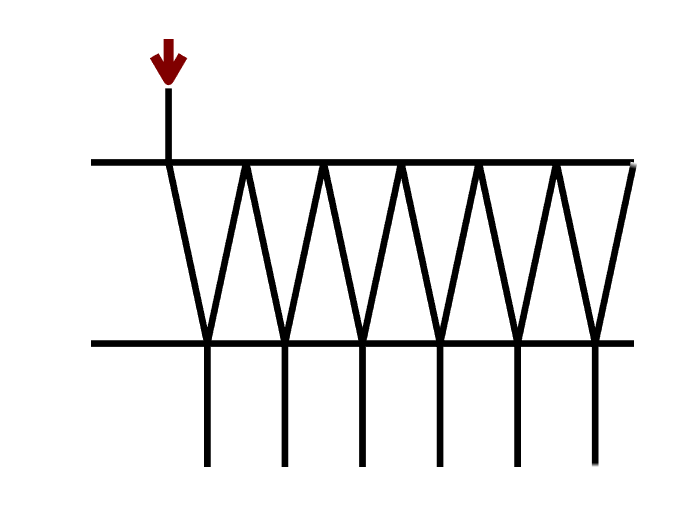

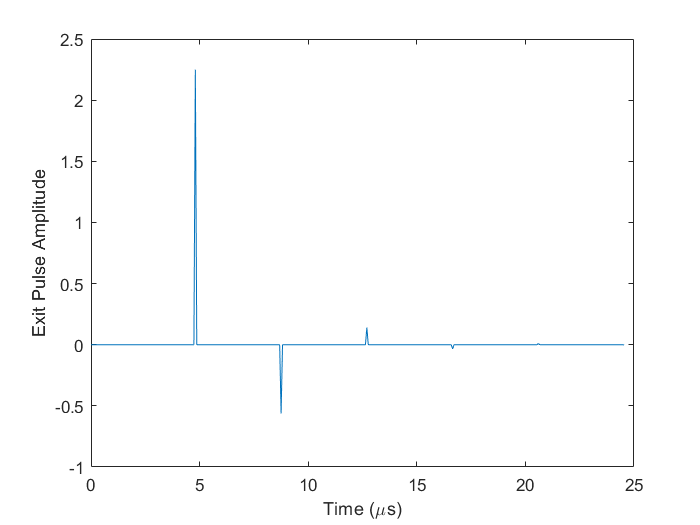

% Draw Lines on ImAxe
plot(ImAxe,1,1);
axis(ImAxe,'off');
axis(ImAxe,[-0.4 1 -1.3 1.3]);
line(ImAxe,[-.4 1], [0.55 0.55],'LineWidth',4,'Color','k');
line(ImAxe,[-.4 1], [-0.55 -0.55],'LineWidth',4,'Color','k');
hold(ImAxe,'on');

%Draws red arrow showing incident beam
quiver(ImAxe, -0.2, 1.5, 0, -.5, ...
    'Color',[0.5 0 0], ...
    'LineWidth',6, ...
    'MaxHeadSize',2);

xS = xS;
yS = yS;
zS = zS;
cS = cS;

lw = 4; %Line width used to drawn lines on app

%Surface commands draws the lines showing the reflection and
%transmission between layers. hS1 is ALL the reflection
%lines between the boundaries. The rest are the incident beam
%and transmission tines. Please look at the matlab surface
%object for additional info.

hS1 = surface(ImAxe,xS(:,:,1),yS(:,:,1),zS,cS,'FaceColor','none','LineWidth',lw,'EdgeColor','interp');
hS2 = surface(ImAxe,xS(:,:,2),yS(:,:,2),zS,cS,'FaceColor','none','LineWidth',lw,'EdgeColor','interp');
hS3 = surface(ImAxe,xS(:,:,3),yS(:,:,3),zS,cS,'FaceColor','none','LineWidth',lw,'EdgeColor','interp');
hS4 = surface(ImAxe,xS(:,:,4),yS(:,:,4),zS,cS,'FaceColor','none','LineWidth',lw,'EdgeColor','interp');
hS5 = surface(ImAxe,xS(:,:,5),yS(:,:,5),zS,cS,'FaceColor','none','LineWidth',lw,'EdgeColor','interp');
hS6 = surface(ImAxe,xS(:,:,6),yS(:,:,6),zS,cS,'FaceColor','none','LineWidth',lw,'EdgeColor','interp');
hS7 = surface(ImAxe,xS(:,:,7),yS(:,:,7),zS,cS,'FaceColor','none','LineWidth',lw,'EdgeColor','interp');
colormap(ImAxe,'gray');
ImAxe.CLimMode = 'manual';
ImAxe.CLim = [0 1];

%%%%%%%%%%%
%Play Movie
%%%%%%%%%%%
%Please note, live editor does not show the movie playing.
%Based on how to program runs, it does all the calculations and returns
%The transmission graph.

% scaling factors
%Time delay is how fast the wave moves through given thickness
timeDelay = 9e-3*(d2/c2)+0.005;
%nSampleTot is the total number of steps the drawing animation
%will have. In this case, it takes 374 steps to represent the
%wave propegating from the beginning to end.
nSampleTot = nSampleTot;
tRx = linspace(0, maxTime*1e6, nSampleTot);
%kend = checkCoefficients() %uncomment to stop movie when
%wave dissipates
for k = 1:nSampleTot
    %Update surfaces so white line representing propegation
    %keeps moving ('where's k?!?')
    cS = updateCData(k,nSampleTot, waves);
    hS1.CData = cS;
    hS1.CData = cS;
    hS2.CData = cS;
    hS3.CData = cS;
    hS4.CData = cS;
    hS5.CData = cS;
    hS6.CData = cS;
    hS7.CData = cS;
    
    %Rx is created weirdly. timeVec has all the right
    %coefficients for transmission and when they should be
    %plotted. That vector is multiplied by a vector of an
    %increasing amount of ones so that when it is plotted in
    %successent cycles, it retains more generated data. 
    Rx = timeVec.* [ones(1,k), zeros(1,nSampleTot-k)];
    plot(LineAxe,tRx,Rx);
    xlabel(LineAxe,'Time (\mus)');
    ylabel(LineAxe,'Exit Pulse Amplitude');
    pause(timeDelay);
end

f = find(Rx);
transmission_values = Rx(f)'

ans =     2.2500
   -0.5625
    0.1406
   -0.0352
    0.0088
   -0.0022



%%%%%%%%%%%%%%%%%%
%External Function
%%%%%%%%%%%%%%%%%%
%Used by movie to procedually update wave propegation

function [cS] = updateCData(sample,nSampleTot,waves)

    if sample<nSampleTot  
        cS = [waves(sample+1,:); waves(sample+1,:)];

    else 
        cS = [waves(end,:); waves(end,:)];
    end
end